clear all
prob=optimproblem; %initializzi il problema

StateUpdate=@(x1,x2)[x1/x2,x1*x2]; %Definisci la funzione di state update, così se dobbiamo passare 
                             %cose costanti come gli speed profiles non dobbiamo
                             %passarli ogni volta. Questa è a caso per
                             %testare
N=100; %Time horizon

SOC_lowerbound=0.20; %Bounds del SOC
SOC_higherbound=0.80;

%Definisci le variabili di ottimizzazione, SOC e mf devono essere
%considerate come tali perché mf ci serve per la funzione di costo mentre
%il SOC è la variabile di stato, ci serve in tutti i punti. Ce ne sono
%altre?
u=optimvar('u',N,"LowerBound",-1,"UpperBound",1);
SOC=optimvar('SOC',N,"LowerBound",SOC_lowerbound,"UpperBound",SOC_higherbound);
mf=optimvar('mf',N);

%Definisci gli equality constraint, se aggiungiamo variabili su cui mettere constraints
% va cambiato il numero N_eq_constraints
N_eq_constraints=2;
eq_constraints=optimconstr(N,N_eq_constraints);

%Lo stato iniziale va fissato
eq_constraints(1,:)= [mf(1),SOC(1)]==[0,0.55];

for i=2:N
    eq_constraints(i,:)= [mf(i),SOC(i)]==StateUpdate(u(i-1),SOC(i-1));
end

prob.Constraints.equality=eq_constraints;

%Definisci gli inqeuality constraint su u, non so se ce ne siano altri
%dinamici, come funziona?
N_in_constr=1;

ineq_constraintsL=optimconstr(N);
ineq_constraintsH=optimconstr(N);
for i=1:N
    ineq_constraintsL(i)= u(i)<= 1;%DA CAPIRE
    ineq_constraintsH(i)= u(i)>=0; %DA CAPIRE
end

prob.Constraints.inequalityL=ineq_constraintsL;
prob.Constraints.inequalityH=ineq_constraintsH;

%Definisci la cost function e gli stati iniziali
prob.Objective=sum(mf); %+sum(SOC-SOC(0))?
initialGuess.u=ones(N,1);

%Simuli tutto con u=0, ora non ho la funzione, quando la avremo non
%servirà più l'inizializzazione punto per punto
initial_SOC=0.55*ones(1,N);
initial_mf=ones(1,N);
%[initial_Tel,initial_Tice,initial_etaice,initial_etael,Minitial_SOC]=

initialGuess.SOC=initial_SOC;
initialGuess.mf=initial_mf;

show(prob)


  OptimizationProblem : 

	Solve for:
       SOC, mf, u

	minimize :
       mf(1) + mf(2) + mf(3) + mf(4) + mf(5) + mf(6) + mf(7) + mf(8) + mf(9) + mf(10) + mf(11) + mf(12) + mf(13) + mf(14) + mf(15) + mf(16) + mf(17) + mf(18) + mf(19) + mf(20) + mf(21) + mf(22) + mf(23) + mf(24) + mf(25) + mf(26) + mf(27) + mf(28) + mf(29) + mf(30) + mf(31) + mf(32) + mf(33) + mf(34) + mf(35) + mf(36) + mf(37) + mf(38) + mf(39) + mf(40) + mf(41) + mf(42) + mf(43) + mf(44) + mf(45) + mf(46) + mf(47) + mf(48) + mf(49) + mf(50) + mf(51) + mf(52) + mf(53) + mf(54) + mf(55) + mf(56) + mf(57) + mf(58) + mf(59) + mf(60) + mf(61) + mf(62) + mf(63) + mf(64) + mf(65) + mf(66) + mf(67) + mf(68) + mf(69) + mf(70) + mf(71) + mf(72) + mf(73) + mf(74) + mf(75) + mf(76) + mf(77) + mf(78) + mf(79) + mf(80) + mf(81) + mf(82) + mf(83) + mf(84) + mf(85) + mf(86) + mf(87) + mf(88) + mf(89) + mf(90) + mf(91) + 

sol=solve(prob,initialGuess)

Solving problem using fmincon.

Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    SOC: [100×1 double]
     mf: [100×1 double]
      u: [100×1 double]


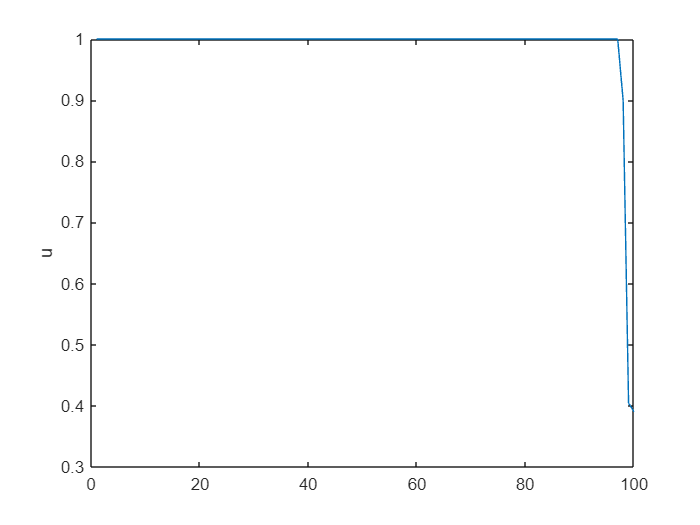

plot(sol.u)
ylabel('u')

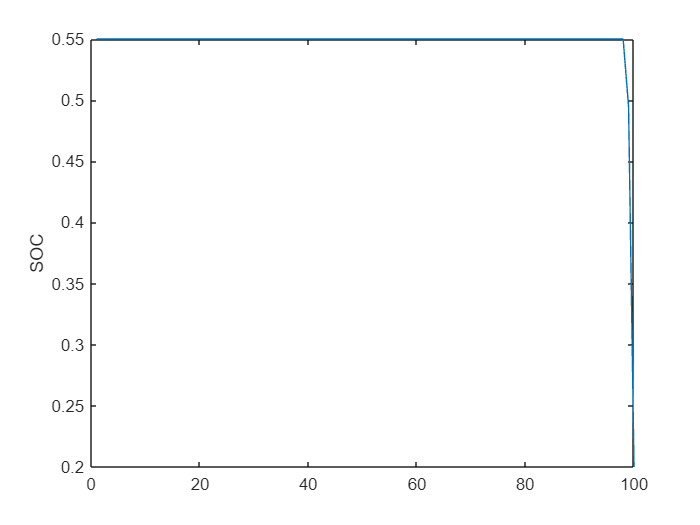

plot(sol.SOC)
ylabel('SOC')

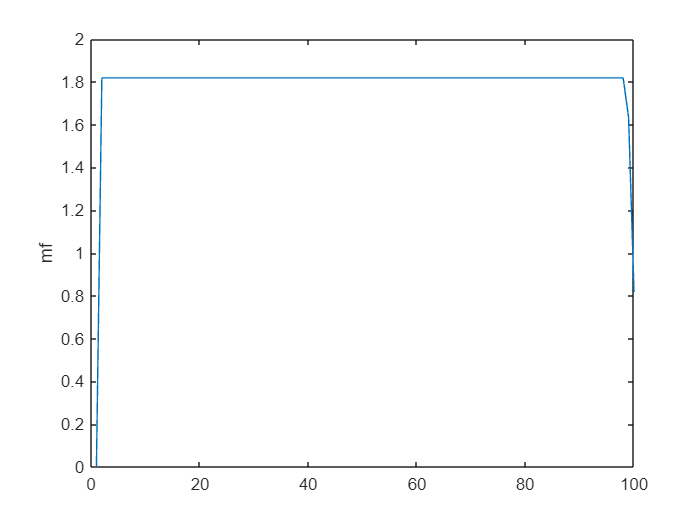

plot(sol.mf)
ylabel('mf')